# Actividad 2.2: Parametrización de trayectorias

**Paola Rojas Domínguez A01737136**

## Inicialización

Se inicia limpiando la consola y la memoria para evitar conflictos de datos anteriores.

clear all
close all
clc

## Ejemplo 1: Cuadrado

Se define el parámetro "t" de parametrización sobre el cual se realizará la proyección de trayectoria

tiempo = [1:1:6];

Se normaliza el intervalo de tiempo al intervalo de variación del ángulo theta. El cambio principal fue modificar el rango de normalización de `t a `$\left\lbrack \pi ,3\ldotp 5\pi \right\rbrack$, lo que alteró los valores de `cos(t)` y `sin(t)` para formar un cuadrado con base una trayectoria circular.

t = normalize(tiempo, "range", [pi, 3.5*pi]);

Obtenemos las ecuaciones dependientes del tiempo

x = ones(1,6).*cos(t);
y = ones(1,6).*sin(t);

Graficamos la trayectoria en coordenadas paramétricas

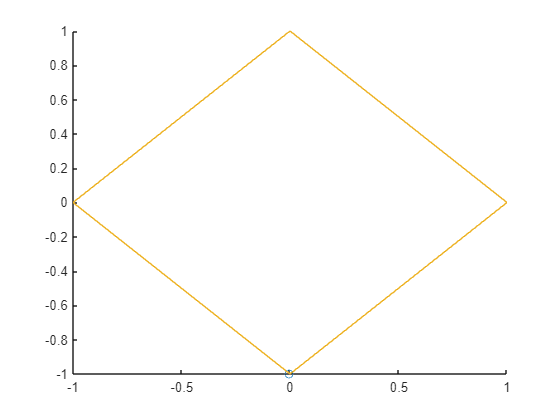

figure(1)
comet(x,y)

## Ejemplo 2: Hexágono

Se define el parámetro "t" de parametrización sobre el cual se realizará la proyeccción de trayectoria. En este caso se aumentó hasta 7. Esto se debe a que un hexágono tiene 6 vértices, pero se necesita un punto adicional para cerrar la figura al repetir el primer vértice al final.

tiempo = [1:1:7];

Se normaliza el intervalo de tiempo al intervalo de variación del ángulo theta. El rango se ajustó a $\left\lbrack \pi ,3\pi \right\rbrack$ para distribuir los puntos de manera uniforme en un hexágono.

t2 = normalize(tiempo, "range", [pi, 3*pi]);

Obtenemos las ecuaciones dependientes del tiempo

x2 = ones(1,7).*cos(t2);
y2 = ones(1,7).*sin(t2);

Graficamos la trayectoria en coordenadas paramétricas

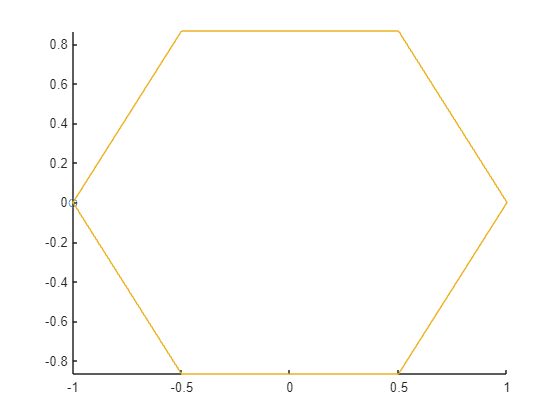

figure(2)
comet(x2, y2)

## Ejemplo 3: Dodecágono

Se define el parámetro "t" de parametrización sobre el cual se realizará la proyección de trayectoria. Se aumentó la cantidad de puntos a 13, lo que genera una trayectoria con 12 vértices.

tiempo = [1:1:13];

Se normaliza el intervalo de tiempo al intervalo de variación del ángulo theta. Se modificó a $\left\lbrack \pi ,3\pi \right\rbrack$, permitiendo distribuir los 12 puntos.

t3 = normalize(tiempo, "range", [pi, 3*pi]);

Obtenemos las ecuaciones dependientes del tiempo

x3 = ones(1,13).*cos(t3);
y3 = ones(1,13).*sin(t3);

Graficamos la trayectoria en coordenadas paramétricas

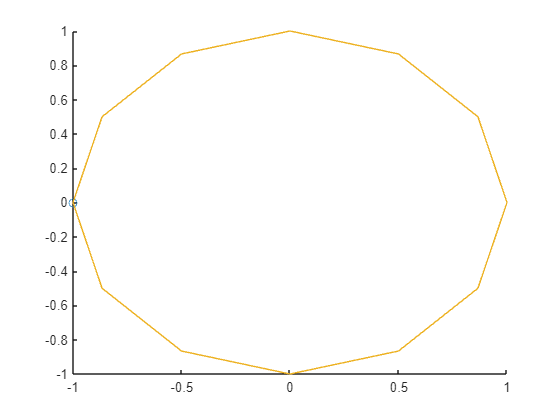

figure(3)
comet(x3, y3)

## Ejemplo 4: Flor de 7 pétalos

Se define el parámetro "t" de parametrización sobre el cual se realizará la proyección de trayectoria

tiempo = [0:0.01:10];

Se normaliza el intervalo de tiempo al intervalo de variación del ángulo theta

t4 = normalize(tiempo, "range", [0, pi]);

Obtenemos las ecuaciones dependientes del tiempo. El coeficiente `50` escala la figura para que tenga un tamaño adecuado en la gráfica. En este caso, `cos(8*t4)` produce `8` oscilaciones

x4 = 50*cos(8*t4).*cos(t4);
y4 = 50*cos(8*t4).*sin(t4);

Graficamos la trayectoria en coordenadas paramétricas

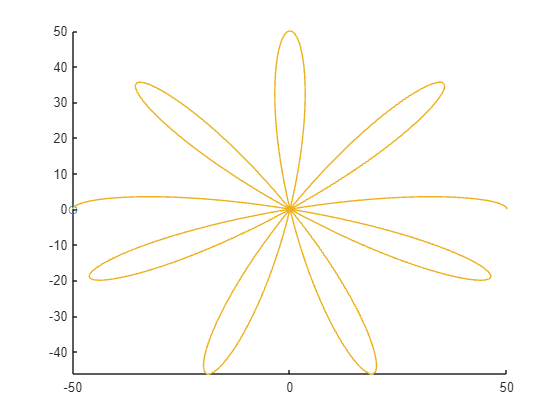

figure(4)
comet(x4, y4)

%plot(x4,y4)

## Ejemplo 5: Flor de 15 pétalos

Se define el parámetro "t" de parametrización sobre el cual se realizará la proyección de trayectoria

tiempo = [0:0.01:10];

Se normaliza el intervalo de tiempo al intervalo de variación del ángulo theta

t5 = normalize(tiempo, "range", [0, pi]);

Obtenemos las ecuaciones dependientes del tiempo. En este caso, `cos(15*t4)` produce 15 oscilaciones

x5 = 5*cos(15*t5).*cos(t5);
y5 = 5*cos(15*t5).*sin(t5);

Graficamos la trayectoria en coordenadas paramétricas

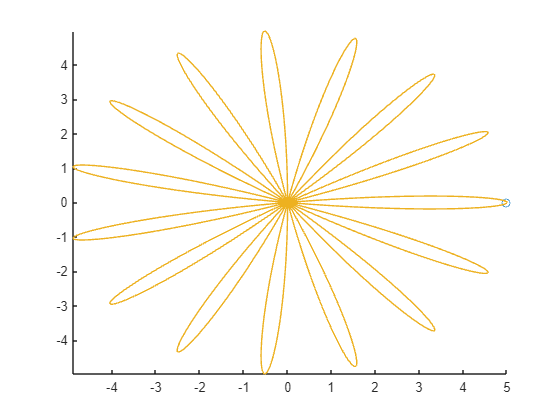

figure(5)
comet(x5, y5)

%plot(x5, y5)

## Ejemplo 6: Flor

Se define el parámetro "t" de parametrización sobre el cual se realizará la proyección de trayectoria

tiempo = [0:0.01:10];

Se normaliza el intervalo de tiempo al intervalo de variación del ángulo theta

t6 = normalize(tiempo, "range", [0, pi]);

Obtenemos las ecuaciones dependientes del tiempo. En este caso, `cos(81*t4)` produce `81` oscilaciones

x6 = 5*cos(81*t6).*cos(t6);
y6 = 5*cos(81*t6).*sin(t6);

Graficamos la trayectoria en coordenadas paramétricas

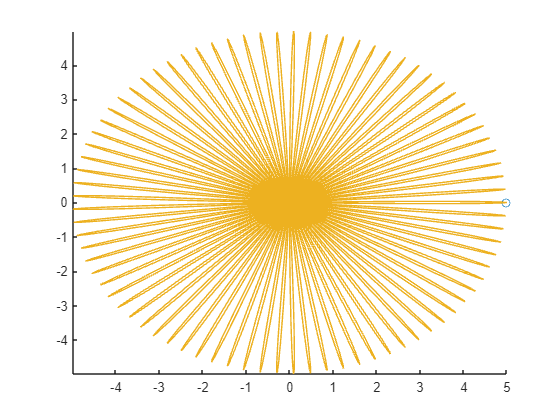

figure(6)
comet(x6, y6)

%plot(x6, y6)